# Lab 3 - Digital Filters Design, Implementation and Analysis

772011 - HASSAN, WAMDAH

772579 - ORR, FINLAY

clear vars; close all; clc;  % Initialise workspace

## Task 2 - Testing the FIR

% Test the FIR filter, and compare its output to the filter() function
x = (1:10);             % Define x as the input 1 to 10
h = [0.2, 0.3, 0.2];    % Define impulse response vector, h
y = myFIR(x, h);        % Filter using the FIR designed in Task 1

figure(1);              % Open a figure window
subplot(1,2,1);         % Focus on graph 1 of 2
grid on;                % Draw gridlines
hold on;                % Hold enables writing titles to graphs
stem(x,y);                      % Plot as stem graph
xlabel('Sample Number (n)');        % Label x axis
ylabel('Amplitude');                % Label y axis
title('myFIR Impulse Response');    % Graph title

y = filter(h,1,x);                  % FIR has no A coefficients, so use 1 instead
subplot(1,2,2);                     % Focus on graph 2 of 2
stem(x,y);                          % Plot as a stem graph for better readibility
grid on;                            % Draw gridlines
hold on;                                % Hold enables writing titles to graphs    
xlabel('Sample Number (n)');                % Label the x axis
ylabel('Filter() Signal Amplitude');        % Label the y axis
title('Filter Function Impulse Response');  % Graph title


% Are the outputs identical? Yes, as they perform the same function.

% What is the transfer function of your filter?
% The tranfer function of a filter is the Z-transform of its impulse response
% .'. H(z) = (0.2) + (0.3z^-1) + (0.2z^-2)

% What is the difference equation of your filter? 
% The general LTI difference equation is:
% Y(z) = X(z) * [ (0.2) + (0.3z^-1) + (0.2z^-2) ]
% Y(z) = (0.2X(z)) + (0.3X(z)z^-1) + (0.2X(z)z^-2)
% Taking the inverse Z-transform gives:
% y(n) = 0.2x(n) + 0.3x(n-1) + 0.2x(n-2)

## Task 3 - Filtering an Impulse Sequence

% Test myFIR using 10 sample long impusle response sequence
x = [1, 0, 0, 0, 0, 0, 0, 0, 0, 0];     % Impulse samples, x
h = [0.2, 0.3, 0.2];                    % Impulse response vector, h

% myFIR Reponse
y = myFIR(x, h);                % Filter samples using myFIR
figure(2);
subplot(2,1,1);                 % Open subplot 1
grid on;                        % Enable gridlines
hold on;
stem(y);                        % Plot filter response on stem graph
xlabel('Sample (n)');           % X axis label
ylabel('Amplitude');            % Y axis label
title('myFIR Impulse Response');    % Graph title

% Filter() Response
y = filter(h, 1, x);            % Filter samples using Filter() function, 'a' coefficients are 1
subplot(2,1,2);                 % Open subplot 2
grid on;
hold on;
stem(y);                        % Plot filter response on stem graph agains sample number
xlabel('Sample (n)');           % X axis label
ylabel('Amplitude');            % Y axis label
title('Filter Function Impulse Response'); % Graph title
% The output could have been predicted, as the impulse response of an FIR filter is
% equal to its coefficients.

% Therefore the output is [0.2, 0.3, 0.2, 0, 0, 0, 0, 0, 0, 0]

## Task 4 - Generate a 1 Second Long Signal

fs = 8000;                  % Sampling frequency of 8KHz
Ts = 1 / fs;                % Sampling period is the inverse of the sampling frequency
t = (0 : Ts : 1);           % One second period, samples every Ts period

% Signal is the sum of three sinusoids:
x = 5*cos(2*pi*(500)*t) + 5*cos(2*pi*(1200)*t + 0.25*pi) + 5*cos(2*pi*(1800)*t + 0.5*pi);

sound(x,fs);                % Play the horrible ERRR sound
figure(3);                  % Open a new figure
plot(t(1:100), x(1:100));   % Plot the first hundred samples
xlabel('Time (s)');         % Label the x axis
ylabel('Signal Amplitude'); % Label the y axis
title('First 100 Samples of Sound Signal'); % Give the graph a title

## Task 5 - Frequency and Impulse Response of FIR Filter

% Coefficients for FIR system 1:
h1 = [-0.0012, -0.0025, -0.0045,-0.0068, -0.0073, -0.0030, 0.0089, 0.0297, 0.0583, 0.0907, 0.1208, 0.1422, 0.1500, 0.1422, 0.1208, 0.0907, 0.0583, 0.0297, 0.0089,- 0.0030, -0.0073, -0.0068, -0.0045, -0.0025, -0.0012];
% Coefficients for FIR system 2:
h2 = [0.0004, -0.0017, -0.0064, -0.0076, 0.0073, 0.0363, 0.0458, 0.0000, -0.0802, -0.1134, -0.0419, 0.0860, 0.1500, 0.0860, -0.0419, -0.1134, -0.0802, 0.0000, 0.0458, 0.0363, 0.0073, -0.0076, -0.0064, -0.0017, 0.0004];

% Plot the impulse response of each filter using stem
% Impluse response of FIR filter is equal to its coefficients!

% For system 1:
figure(4);                  % Designate a new figure window
grid on;                    % Enable gridlines
hold on;
stem(h1);                   % Plot the impulse response of system 1 on a stem graph
xlabel('Sample Index');     % Label x axis
ylabel('Amplitude');        % Label y axis
title('Impulse Response of FIR System 1');  % Title the graph
                 
% For system 2:
figure(5);                  % New figure window
stem(h2);                   % Plot the impulse response for system 2 on a stem graph
grid on;                    % Enable gridlines
hold on;
xlabel('Sample Index');     % Label x axis
ylabel('Amplitude');        % Label y axis
title('Impulse Response of FIR system 2');  % Title graph

% Redefine parameters from Task 4 for 'Run Section' compatibility
x = 5*cos(2*pi*(500)*t) + 5*cos(2*pi*(1200)*t + 0.25*pi) + 5*cos(2*pi*(1800)*t + 0.5*pi);   % Sound signal 
fs = 8000;                  % Sampling frequency of 8KHz
Ts = 1 / fs;                % Sampling period is the inverse of the sampling frequency
t = (0 : Ts : 1);           % One second period, samples every Ts period

% Filter the signal from task 4 using the coefficients from system 1 and 2
y1 = myFIR(x, h1);          % Filtered using system 1 coeff
y2 = myFIR(x, h2);          % Filtered using system 2 coeff

% Plot the input signal spectrum and the output signal spectra for each
% filter using the frequency resolution of 1Hz
in_spec   = fft(x);         % Perform DFT on the input sequence
sys1_spec = fft(y1);        % Compute the DFT of system 1 samples
sys2_spec = fft(y2);        % Compute the DFT of system 2 samples

figure(6);
subplot(3,1,1);                     % First subplot: FIR System 2
stem(t, abs(in_spec));              % Plot the stem graph using the absolute value of the input spectrum due to complex data
grid on;                            % Enable gridlines
hold on;                            % Hold to enable writing titles to graphs
title('Input Signal Spectrum');     % Title the graph


subplot(3,1,2);                     % Second subplot : FIR System 1
stem(t, abs(sys1_spec));            % Plot the stem graph of System 1's spectrum, using abs again to mitigate complex data
grid on;                            % Enable gridlines
hold on;                            % Hold on to enable writing titles to graphs
title('System 1 Signal Spectrum');  % Title the graph

subplot(3,1,3);
stem(t, abs(sys2_spec));            % Plot the spectrum against the time
grid on;                            % Enable gridlines
hold on;                            % Hold to enable writing titles to graphs
title('System 2 Signal Spectrum');  % Graph title

% Spectral peaks are located at:
% Input Spectrum        : 0.0625, 0.15, 0.225
% System 1 Spectrum (h1): 0.0625
% System 2 Spectrum (h2): 0.0625, 0.15, 0.225

% Play the input signal, and the filtered output from each signal
sound(x, fs);   % Play the input signal
pause(1.5);     % Pause for half a second
sound(y1, fs);  % Play the signal filtered with h1
pause(2.5);     % Pause for a second
sound(x, fs);   % Play the input signal again
pause(1.5);     % Wait for half a second
sound(y2, fs);  % Play the signal filtered with h2

% The signal from system 1 sounds a lower pitch than the input signal and system 2. From the stem graph, we
% can see the higher frequencies have been greatly attenuated in system 1.
% It has a clean sinusoidal ringing sound, this is due to the few
% fundamental frequencies present in the spectrum.

% The signal from system 2 sounds a higher pitch than both the input and
% system-1. This is indicated in the stem graph by the location of the
% speactral peak. System 2 does not attenuate the lower and higher components as well
% as system 1, this is heard as a not so clean sine wave ringing.

## Task 6 - Frequency Analysis of FIR Filter

% Freqz returns h, the n-point frequence response vector and the
% corresponding angular frequency vector, w.

% Sampling frequency of 8KHz
fs = 8000;                  
% Coefficients for FIR system 1:
h1 = [-0.0012, -0.0025, -0.0045,-0.0068, -0.0073, -0.0030, 0.0089, 0.0297, 0.0583, 0.0907, 0.1208, 0.1422, 0.1500, 0.1422, 0.1208, 0.0907, 0.0583, 0.0297, 0.0089,- 0.0030, -0.0073, -0.0068, -0.0045, -0.0025, -0.0012];
% Coefficients for FIR system 2:
h2 = [0.0004, -0.0017, -0.0064, -0.0076, 0.0073, 0.0363, 0.0458, 0.0000, -0.0802, -0.1134, -0.0419, 0.0860, 0.1500, 0.0860, -0.0419, -0.1134, -0.0802, 0.0000, 0.0458, 0.0363, 0.0073, -0.0076, -0.0064, -0.0017, 0.0004];

% Generate the frequency response for system 1 and 2
[freqz_h1, w_h1] = freqz(h1, 1, fs);
[freqz_h2, w_h2] = freqz(h2, 1, fs);

figure(7);
subplot(2,2,1);                     % Plot 1 is the impulse response of system 1
grid on;
hold on;
impz(h1, 1, length(h1), fs);        % Generate inpulse response of filter, using absolute values of h1 due to complex components
xlabel('Time (s)'); 
ylabel('Amplitude');
title('System 1 Impulse Response');

subplot(2,2,2);                     % Plot 2 is the impulse response of system 2
grid on;
hold on;
impz(h2, 1, length(h2), fs);        % Generate impulse response for system 2
xlabel('Time (s)');                 % X axis label
ylabel('Amplitude');                % Y axis label
title('System 2 Impulse Response'); % Graph title

subplot(2,2,3);                         % Plot 3 is the frequency response for system 1, obtain using freqz function
grid on;
hold on;
plot(w_h1, 20*log10(abs(freqz_h1)));    % Plot the frequency response for system 1 (h1): magnitude in dB
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('System 1 Frequency Response');

subplot(2,2,4);                         % Plot 4 is the frequency response for system 2, calculated using freqz function
grid on;
hold on;
plot(w_h2, 20*log10(abs(freqz_h2)));    % Plot the frequency response for system 2, magnitude is in dB (20log10(A))
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('System 2 Frequency Response');

% (The frequency x axis looks strange?)

% The impulse reponse is identical to the one obtained previously.
% The frequency response shows how signals are attenuated.
% 
% In task 5 we stated that system 1 attenuates the higher frequencies
% more than system 2. This is shown in the frequency response graph, where
% system 1 has a greater attentuation around 1Hz. 
% 
% System 2 did not attenuate the components around the spectral peak as
% much as system 1 did. This can be seen in the 'System 2 Frequency Response'
% graph, where there is a wide 1.5 Hz pass band of signals not attenuated.

## Task 7 - Filtering Speech

WE = load("WE.DAT");        % Load the WE.DAT speech file
fs = 8000;                  % 8KHz sampling frequency
Ts = 1/fs;                  % Sampling period is the reciprocal of the sampling frequency
t = (0:length(WE)-1) * Ts;  % Time vector for the speech signal, staring at zero, with one sample every sampling period

% Coefficients for FIR system 1:
h1 = [-0.0012, -0.0025, -0.0045,-0.0068, -0.0073, -0.0030, 0.0089, 0.0297, 0.0583, 0.0907, 0.1208, 0.1422, 0.1500, 0.1422, 0.1208, 0.0907, 0.0583, 0.0297, 0.0089,- 0.0030, -0.0073, -0.0068, -0.0045, -0.0025, -0.0012];
% Coefficients for FIR system 2:
h2 = [0.0004, -0.0017, -0.0064, -0.0076, 0.0073, 0.0363, 0.0458, 0.0000, -0.0802, -0.1134, -0.0419, 0.0860, 0.1500, 0.0860, -0.0419, -0.1134, -0.0802, 0.0000, 0.0458, 0.0363, 0.0073, -0.0076, -0.0064, -0.0017, 0.0004];

y1 = myFIR(WE, h1);         % Filter the speech signal using the coefficients given in system 1
y2 = myFIR(WE, h2);         % Filter the speech signal using the coefficients given in system 2

figure(8);                  % New figure to display the signal spectra
subplot(3,1,1);             % Plot 1 - unfiltered input signal  
plot(t, WE);
grid on;
% hold on;                  % Keep hold commented if replaying sound
title('WE.DAT Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);             % Plot 2 -signal filtered using system 1 coefficients
plot(t, y1);
grid on;
% hold on;
title('Speech Filtered with h1 Coeff');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);             % Plot 3 - signal filtered using system 2 coefficients
plot(t, y2);
grid on;
% hold on;
title('Speech Filtered with h2 Coeff');
xlabel('Time (s)');
ylabel('Amplitude');

% Play and listen to the two filtered speech signals
sound(WE, fs);  % Original input speech first
pause(1);     
sound(y1, fs);  % Filtered using h1 

pause(2);       % Delay between signals to differentiate which is which

sound(WE, fs);  % Input speech again
pause(1);     
sound(y2, fs);  % Now the speech filtered using h2
pause(1);

% The speech sounds corrupted with high frequency noise.
% By filtering the speech with FIR h1, these frequencies are attenuated and
% the speech becomes clearer. However when the speech is applied to the FIR
% with coefficients h2, the speech frequencies become attenuated and the
% noise remains, which is what is heard.

% The higher frequency components corresponding to the speech, can be seen 
% in the third plot, 'Speech Filtered with h1 Coeff'. The lower frequency 
% elements of the signal are not attenuated using h1- these are extracted 
% and shown in the second plot, 'Speech Filtered with h1 Coeff'.

## Task 8 - Speaker Design

% Design a lowpass and highpass filter in parallel to seperate signals so
% they can be fed into tweeters and subwoofers
% use help designfilt for more information

fs = 44100;             % Sampling frequency of 44.1KHz

%       LOWPASS FILTER      %
lp_passband = 600;      % Pass band   : 0 -> 600 Hz
lp_stopband = 1400;     % Stopband    : 1.4 KHz
lp_ripple   = 0.02;     % Ripple      : 0.02 dB
lp_att      = 50;       % Attenuation : 50   dB

lp_filter = designfilt('lowpassfir','PassbandFrequency',lp_passband, 'StopbandFrequency', lp_stopband, 'PassbandRipple', lp_ripple, 'StopbandAttenuation', lp_att, 'SampleRate', fs);

%       LOWPASS FILTER      %
hp_passband = 1400;     % Pass band   : 1400 -> 4100 Hz
hp_stopband = 600;      % Stopband     : 600 Hz
hp_ripple   = 0.02;     % Ripple      : 0.02 dB
hp_att      = 50;       % Attenuation : 50   dB

hp_filter = designfilt('highpassfir','PassbandFrequency',hp_passband, 'StopbandFrequency', hp_stopband, 'PassbandRipple', hp_ripple, 'StopbandAttenuation', hp_att, 'SampleRate', fs);

% Open filters using MATLAB Filter Visualisation Tool (FVTool)
fvtool(lp_filter);
fvtool(hp_filter);

## Task 9 - Cascaded Notch Filter

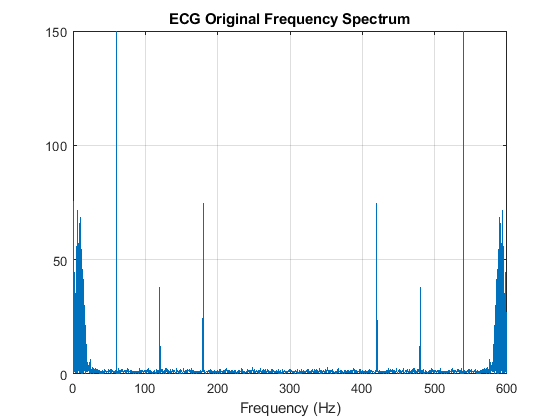

% Design three second order notch filters to attenuate the interference at
% 60, 120 and 180 Hz.
% Notch filter can be designed with two zeros at +-jw

ECG = load('ecgbn.dat');
N = length(ECG);            % N samples in ECG
fs = 600;                   % Sampling frequency of 600 Hz
f = (0:N-1) * fs / N;       % Fill vector f with fixed freq samples

% Plot the frequency spectrum of the input
y = fft(ECG);
figure(9);
plot(f,abs(y));
hold on;
grid on;
title('ECG Original Frequency Spectrum');
xlabel('Frequency (Hz)');

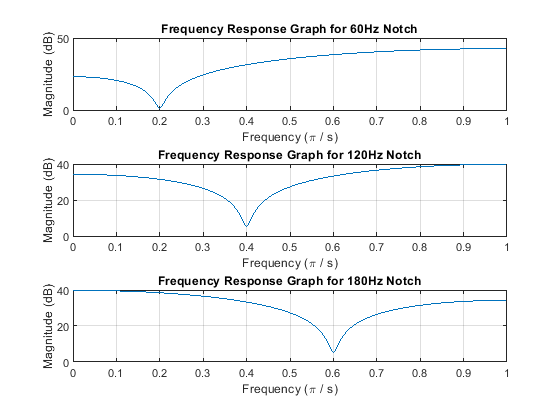


% Begin filter
R = 0.974;          % Zero distance from origin
a = 1-R;            % TF numerator

% Using zero placement method, the following TF were derived:
b1 = [1 -R*1.618 (R^2)];    % 60 Hz Notch Filter tf denominator, b
b2 = [1 -R*0.618 (R^2)];    % 120 Hz notch filter tf denominator, b
b3 = [1 +R*0.618 (R^2)];    % 180 Hz notch filter tf demonimator, b

% Analyse the frequency response of the threee notch filter seperately
[h1, w1] = freqz(b1, a);    
[h2, w2] = freqz(b2, a);
[h3, w3] = freqz(b3, a);

subplot(3,1,1);
plot(w1/pi, 20*log10(abs(h1))); % Plot the frequency response using MATLAB ex format
grid on;
hold on;
xlabel('Frequency (\pi / s)');
ylabel('Magnitude (dB)');
title('Frequency Response Graph for 60Hz Notch');

subplot(3,1,2);
plot(w2/pi, 20*log10(abs(h2))); % Plot the frequency response using MATLAB ex format
grid on;
hold on;
xlabel('Frequency (\pi / s)');
ylabel('Magnitude (dB)');
title('Frequency Response Graph for 120Hz Notch');

subplot(3,1,3);
plot(w3/pi, 20*log10(abs(h3))); % Plot the frequency response using MATLAB ex format
grid on;
hold on;
xlabel('Frequency (\pi / s)');
ylabel('Magnitude (dB)');
title('Frequency Response Graph for 180Hz Notch');


% Three notch filters at w0 = pi/5, 2pi/5, 3pi/5
H1 = dfilt.df2t(b1,a);
H2 = dfilt.df2t(b2,a);
H3 = dfilt.df2t(b3,a);          

HCascade = dfilt.cascade(H1, H2, H3); % Cascade filters using MATLAB dfilt
info(HCascade)                        % To view details of the cascaded filter

Discrete-Time FIR Filter (real)
-------------------------------
Filter Structure  : Cascade    
Number of Stages  : 3          
Stable            : Yes        
Linear Phase      : No         


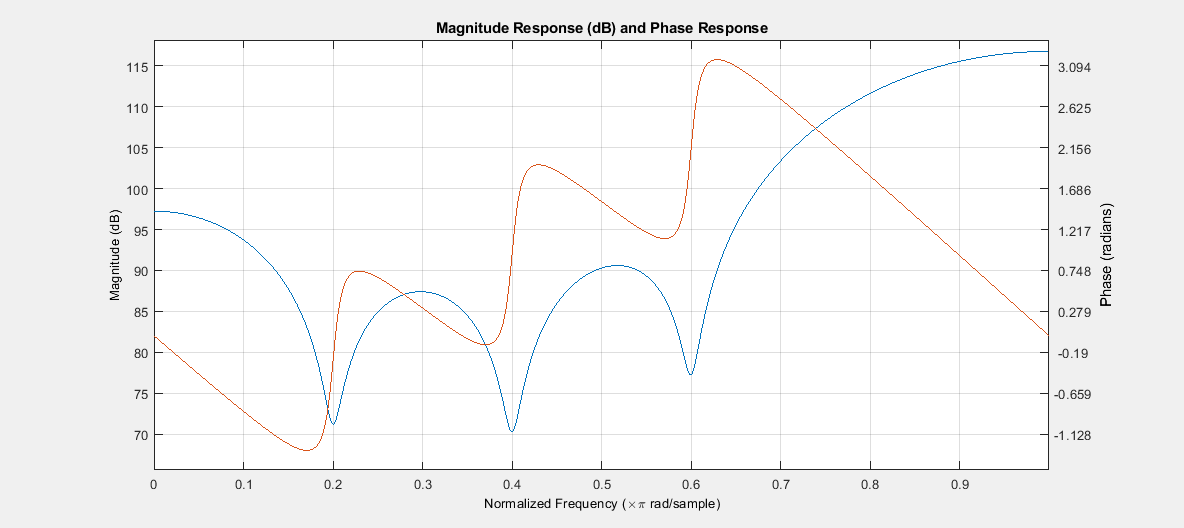

HCascade.freqz();                     % Frequency response of cascaded notch filters

## Task 10 - IIR Filter Frequency Response

theta = pi/3;       % Define theta
R1 = 0.99;          % Define the values for R:
R2 = 0.9;           % R is the distance from origin to pole
R3 = 0.8;           % to get a 3dB drop in frequency response

% Numerator of the transfer function, a
a1 = 1-R1;          
a2 = 1-R2;
a3 = 1-R3;

% Transfer function denominator, b
b1 = [1 -2*R1*cos(theta) (R1^2)];  
b2 = [1 -2*R2*cos(theta) (R2^2)];
b3 = [1 -2*R3*cos(theta) (R3^2)];

% Using freqz again to calculate the frequency response
[h1, w1] = freqz(b1, a1);       % Frequency response for R1
[h2, w2] = freqz(b2, a2);       % Frequency response for R2
[h3, w3] = freqz(b3, a3);       % Frequency response for R3

figure(10);                     % Open new figure window
subplot(3,1,1);
plot(w1/pi, 20*log10(abs(h1))); % Plot the frequency response using MATLAB ex format
grid on;
hold on;
xlabel('Frequency (\pi / s)');
ylabel('Magnitude (dB)');
title('Frequency Response Graph for R1');

subplot(3,1,2);
plot(w2/pi, 20*log10(abs(h2))); % Plot the frequency response using MATLAB ex format
grid on;
hold on;
xlabel('Frequency (\pi / s)');
ylabel('Magnitude (dB)');
title('Frequency Response Graph for R2');

subplot(3,1,3);
plot(w3/pi, 20*log10(abs(h3))); % Plot the frequency response (for w < pi)
grid on;
hold on;
xlabel('Frequency (\pi / s)');
ylabel('Magnitude (dB)');
title('Frequency Response Graph for R3');

% Decreasing the value of R increases the attentuation.
% As R is the distance from the origin to the pole, as the pole gets
% further from the unit circle the attenuation is increased.

## Task 11 - Effect of Varying Theta on IIR Filter Frequency Response

% Define increasing values for theta
theta1 = pi / 6;    
theta2 = pi / 3;
theta3 = pi / 2;

R = 0.9;            % R is constant 0.9
a = 1-R;            % Numerator of the transfer function, a

% Calculate the denominators of the transfer function, b
b1 = [1 -2*R*cos(theta1) (R^2)];        % PREVIOUS ERROR WAS (1-2*R*cos(thetaN)*(R^2))
b2 = [1 -2*R*cos(theta2) (R^2)];
b3 = [1 -2*R*cos(theta3) (R^2)];

% Generate frequency response from the transfer functions
[h1, w1] = freqz(b1,a);
[h2, w2] = freqz(b2,a);
[h3, w3] = freqz(b3,a);

% Plot the frequency response on a graph
figure(11);
subplot(3,1,1);
plot(w1/pi, 20*log10(abs(h1))); % Plot the frequency response using MATLAB ex format
grid on;
hold on;
xlabel('Frequency (\pi / s)');
ylabel('Magnitude (dB)');
title('Graph 1: Frequency Response for Theta = (\pi/6)');

subplot(3,1,2);
plot(w2/pi, 20*log10(abs(h2))); % Plot the frequency response using MATLAB ex format
grid on;
hold on;
xlabel('Frequency (\pi / s)');
ylabel('Magnitude (dB)');
title('Graph 2: Frequency Response for Theta = (\pi/3)');

subplot(3,1,3);
plot(w3/pi, 20*log10(abs(h3))); % Plot the frequency response (for w < pi)
grid on;
hold on;
xlabel('Frequency (\pi / s)');
ylabel('Magnitude (dB)');
title('Graph 3: Frequency Response for Theta = (\pi/2)');

% As theta decreases, the passband for the filter increases- this is shown
% in graphs 2 and 3. This corresponds with moving the poles around the unit
% circle and their filter response.

% Theta is the location of the rejection frequency. Increasing theta does
% not affect the magnitude, but it does effect the location of the
% rejection notch.

## Task 13

% Generate impulse signal
l = 1000;
d1 = zeros(1,l);
d1(1)=1;
fs = 8000;

% Generate filter from Task 12
bsFilt = designfilt('bandstopiir','FilterOrder',20, ...
         'HalfPowerFrequency1',3100,'HalfPowerFrequency2',3250, ...
         'SampleRate',fs);

% Perform filtering and fft
x = filter(bsFilt, d1);
x_spec = fft(x);


% Plot signal and spectrum
figure('Name', 'Filtered Signal, fs = 8kHz', 'NumberTitle', 'off');

subplot(3,1,1);
stem(0:1/fs:(1/fs*l-1/fs), d1);
title('Original Signal');
xlabel('Time(s)');
ylabel('');
grid;

subplot(3,1,2);
plot(0:1/fs:(1/fs*l-1/fs), x);
title('Filtered Signal');
xlabel('Time(s)');
ylabel('');
grid;

subplot(3,1,3);
stem(0:fs/l:fs-fs/l, x_spec);

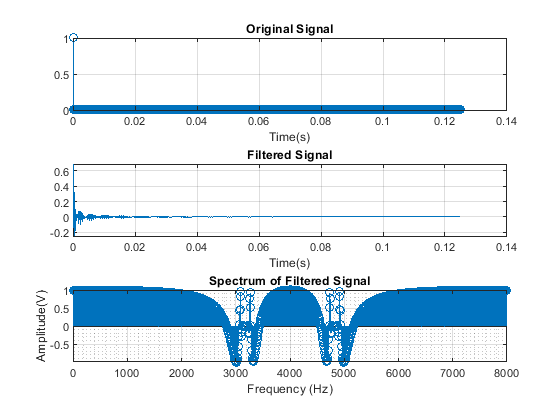

title('Spectrum of Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude(V)');
grid;
grid minor;

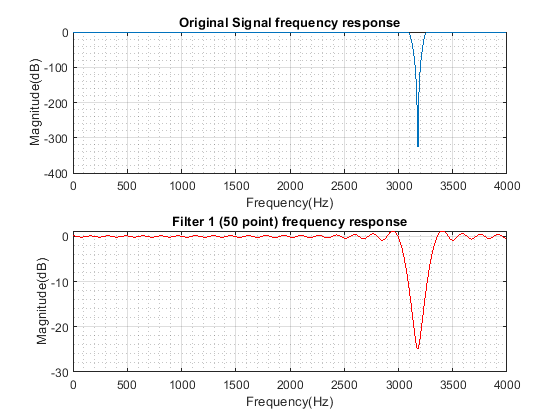



% Generate FIR specs
l1 = 50;
l2 = 100;
l3 = 150;

h1 = x(1:l1);
h2 = x(1:l2);
h3 = x(1:l3);


[h00,w0] = freqz(bsFilt);
[h01,w1] = freqz(h1,1);
[h02,w2] = freqz(h2,1);
[h03,w2] = freqz(h3,1);

% Plotting of 3 comparisons
figure('Name', 'Frequency response 1', 'NumberTitle', 'off');

subplot (2, 1, 1);
plot(w1*fs/(2*pi),mag2db(abs(h00)));
title('Original Signal frequency response');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');
grid;
grid minor;

subplot (2, 1, 2);
plot(w1*fs/(2*pi),mag2db(abs(h01)), '-r');
title('Filter 1 (50 point) frequency response');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');
grid;
grid minor;

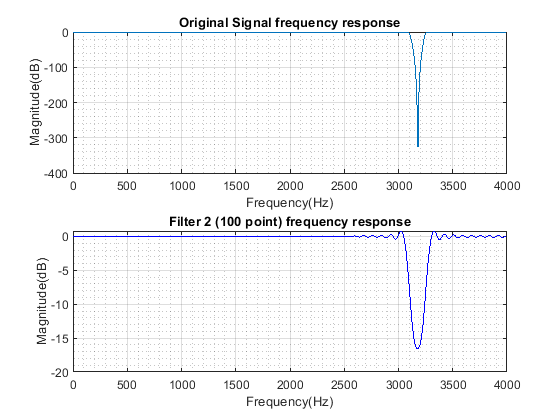



figure('Name', 'Frequency response 2', 'NumberTitle', 'off');

subplot (2, 1, 1);
plot(w1*fs/(2*pi),mag2db(abs(h00)));
title('Original Signal frequency response');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');
grid;
grid minor;

subplot (2, 1, 2);
plot(w1*fs/(2*pi),mag2db(abs(h02)), '-b');
title('Filter 2 (100 point) frequency response');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');
grid;
grid minor;

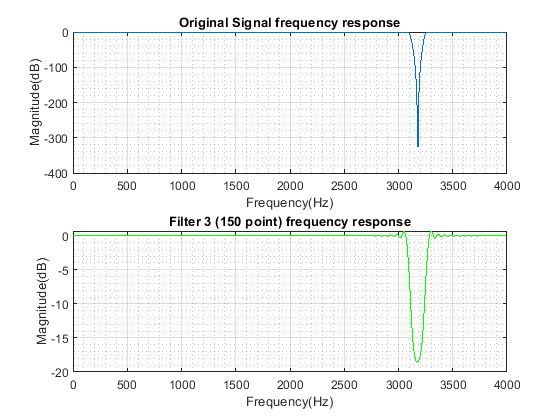



figure('Name', 'Frequency response 3', 'NumberTitle', 'off');

subplot (2, 1, 1);
plot(w1*fs/(2*pi),mag2db(abs(h00)));
title('Original Signal frequency response');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');
grid;
grid minor;

subplot (2, 1, 2);
plot(w1*fs/(2*pi),mag2db(abs(h03)), '-g');
title('Filter 3 (150 point) frequency response');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');
grid;
grid minor;

## Task 1

function y = myFIR(x, h)    

    M = length(h);      % M : the number of b coefficients
    N = length(x);      % N : the number of input samples
    
    for n = 1:N         % Loop through samples
        y(n) = 0;       % Clear y(n) between samples
        for k = 1:M     % Loop through coefficients
            if (n + 1 - k) > 0                          % Arrays in MATLAB start at 1
                y(n) = y(n) + (h(k) * x(n + 1 - k));    % FIR filter equation
            end
        end
    end
end